org = Org; org.init;

We want to to measure the average degree of place field overlap between all pairs of cells. One simple way to do this is to find the mean correlation between all pairs of neurons of their mean responses, using the data binned into 20 left and 20 right bins.

mus = cell2mat(org.vars.mus{6});
[~, max_ix] = max(mus(:,1:20), [], 2);
[~, ord] = sort(max_ix);

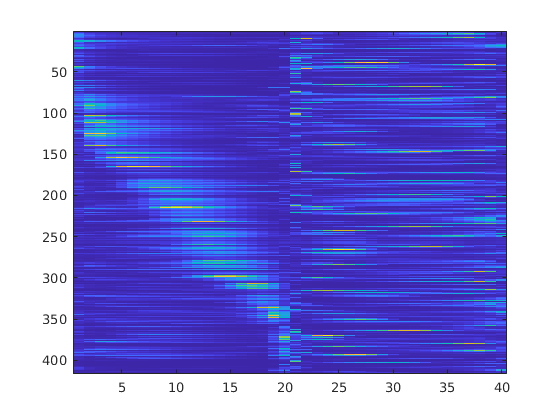

figure;
imagesc(mus(ord,:));

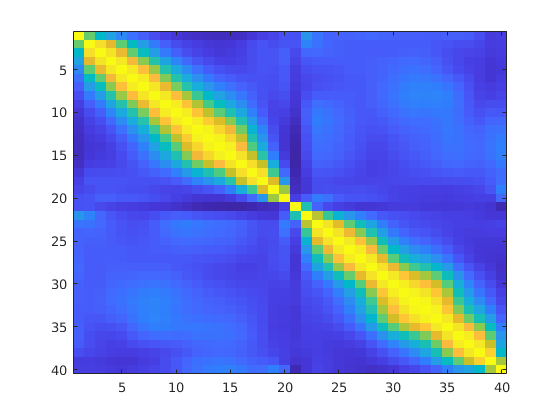

figure; imagesc(corr(mus))

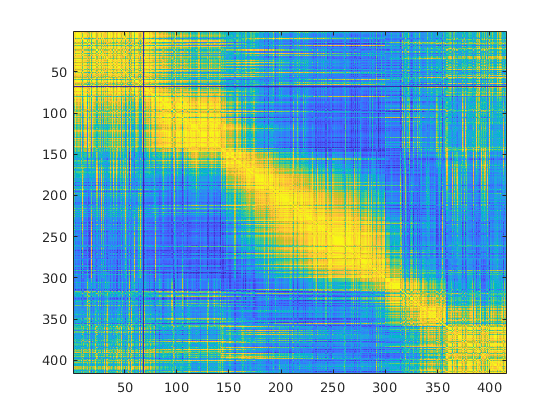

r_side_corrs = corr(mus(ord,1:20).');
figure; imagesc(r_side_corrs);

mean_corr(r_side_corrs)

ans = 0.0212

overlap_metric(org.vars.mus{69})

ans = 0.0384

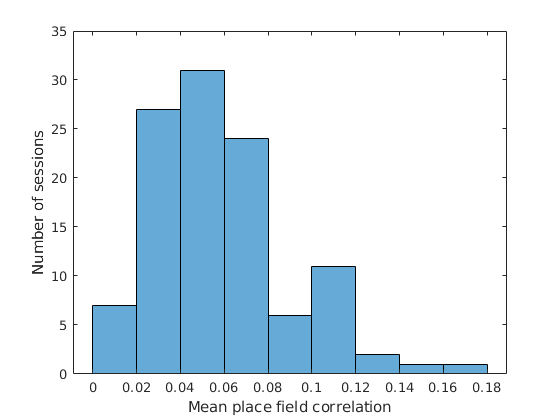

overlaps = cellfun(@overlap_metric, org.vars.mus);
figure;
histogram(overlaps);
xlabel 'Mean place field correlation'
ylabel 'Number of sessions'

figure;
org.correlogram('signal_var_norm', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations signal_var_norm vs. asymp_ratio: adj. R^2 = 0.653
Pearson: 0.831, p = 2.865243e-03, **
Spearman: 0.636, p = 5.444507e-02, n.s.
Kendall: 0.511, p = 4.662257e-02, *


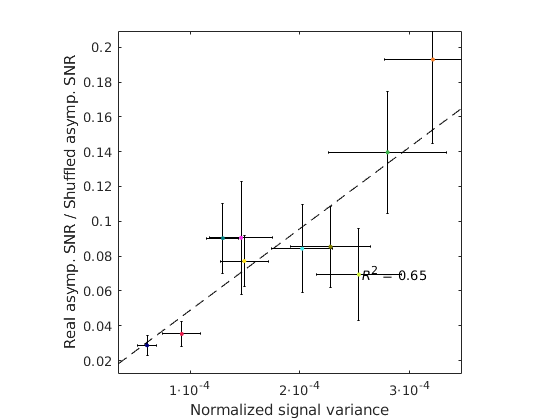

axis square
set(gca, 'XTick', [1 2 3]*1e-4);
Utils.fix_exponent(gca, 'x', 0);
ylabel 'Real asymp. SNR / Shuffled asymp. SNR'
xlabel 'Normalized signal variance'

figure;
org.correlogram('hd_svn', 'hd_asymp_ratio', true, true, true);

Using only 34 out of 110 sessions
Mouse-aggregated correlations hd_svn vs. hd_asymp_ratio: adj. R^2 = 0.863
Pearson: 0.939, p = 5.295725e-04, ***
Spearman: 0.952, p = 1.140873e-03, **
Kendall: 0.857, p = 1.736111e-03, **


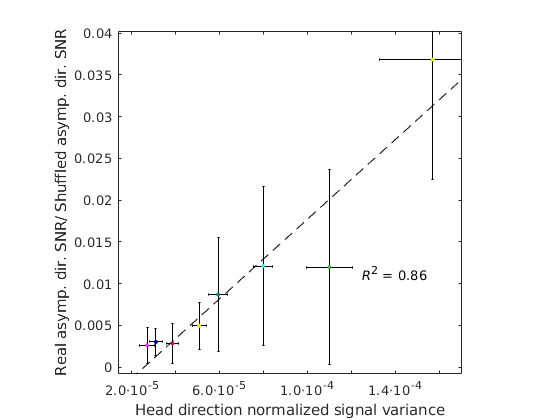

xlabel 'Head direction normalized signal variance'
ylabel 'Real asymp. dir. SNR/ Shuffled asymp. dir. SNR'
Utils.fix_exponent(gca, 'x', 1);
axis square

figure;
org.correlogram('overlap_metric', 'asymp_ratio', true, true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations overlap_metric vs. asymp_ratio: adj. R^2 = -0.122
Pearson: -0.048, p = 8.961675e-01, n.s.
Spearman: -0.248, p = 4.915555e-01, n.s.
Kendall: -0.156, p = 6.006537e-01, n.s.


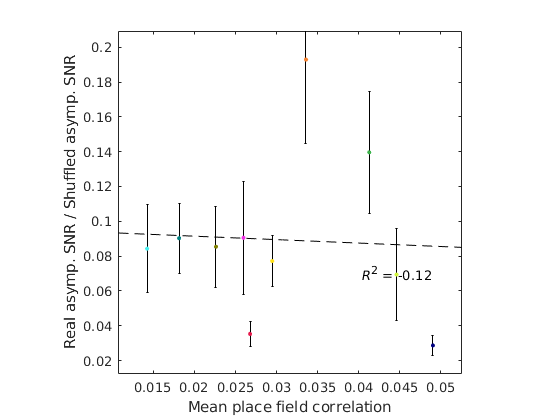

axis square
ylabel 'Real asymp. SNR / Shuffled asymp. SNR'
xlabel 'Mean place field correlation'
Utils.printto('events_figs/f5_supplements', 'overlap_vs_asymp_ratio.pdf');

figure;
org.correlogram('overlap_metric', 'hd_asymp_ratio', true, true, true);

Using only 34 out of 110 sessions
Mouse-aggregated correlations overlap_metric vs. hd_asymp_ratio: adj. R^2 = -0.159
Pearson: 0.083, p = 8.447271e-01, n.s.
Spearman: -0.262, p = 5.364087e-01, n.s.
Kendall: -0.214, p = 5.484127e-01, n.s.


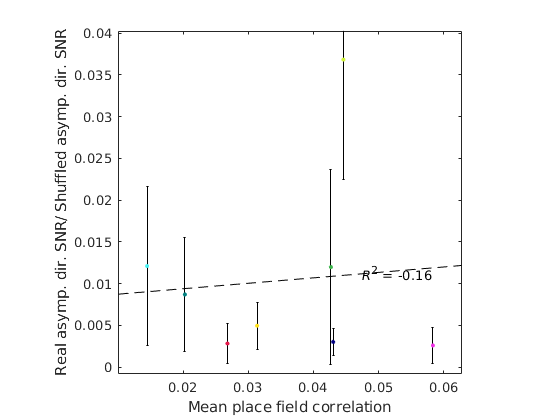

axis square
ylabel 'Real asymp. dir. SNR/ Shuffled asymp. dir. SNR'
xlabel 'Mean place field correlation'
Utils.printto('events_figs/f5_supplements', 'overlap_vs_hd_asymp_ratio.pdf');

function r = overlap_metric(mus)
mus = cell2mat(mus);
r = mean_corr(corr(mus(:,1:20).')) + mean_corr(corr(mus(:,21:40).'));
end
function r = mean_corr(C)
keep = ~isnan(diag(C));
C = C(keep, keep);
n = size(C,1);
r = (sum(C, 'all') - n)./(n^2-n);
end